clc
clear all
close all
% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
wpts = [0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0];
% tpts = 0:5;
tpts = 0:sqrt(8):sqrt(8)*8*4;

numsamples = 100*4;

[q,qd,qdd,qddd,qdddd,pp,timepoints,tsamples] = minsnappolytraj(wpts,tpts,numsamples);

%plot(tsamples,q);
%plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
%python
disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

  Columns 1 through 10

         0    2.8284    5.6569    8.4853   11.3137   14.1421   16.9706   19.7990   22.6274   25.4558

  Columns 11 through 20

   28.2843   31.1127   33.9411   36.7696   39.5980   42.4264   45.2548   48.0833   50.9117   53.7401

  Columns 21 through 30

   56.5685   59.3970   62.2254   65.0538   67.8823   70.7107   73.5391   76.3675   79.1960   82.0244

  Columns 31 through 33

   84.8528   87.6812   90.5097



size(q(2,:))

ans =      1   400


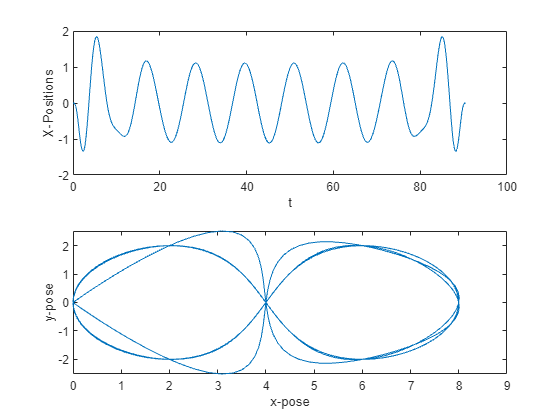

%disp (q);
%hold on
%plot(timepoints,wpts,'x')
figure(1)
subplot(2,1,1) 
plot(tsamples, q(2,:))
xlabel('t');
ylabel('Y-Positions');
subplot(2,1,2) 
plot(q(1,:), q(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')


%legend('X-positions','Y-positions')

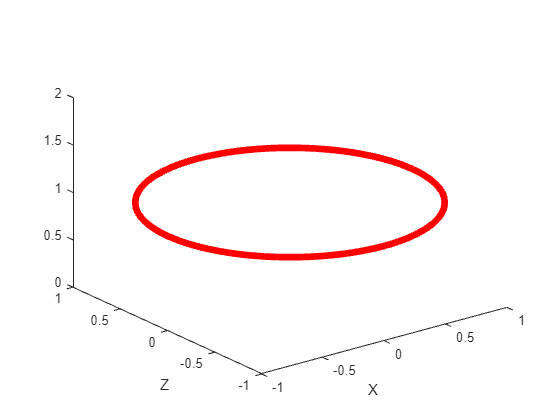

clc
clear all
close all
[c,x,y] = circle(0,0,1);

disp (size(x));

     1   101




% Specify waypoints, times of arrival, and sampling rate. 
wp = [0 0 0; 2 -2 0; 4 0 0; 6 2 0; 8 0 0; 6 -2 0; 4 0 0; 2 2 0; 0 0 0];
toa = sqrt(8)*(0:size(wp,1)-1).'

toa =          0
    2.8284
    5.6569
    8.4853
   11.3137
   14.1421
   16.9706
   19.7990
   22.6274


vel = [0 0 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 0 0 0];
Fs = 100; % resolution

% Create trajectory. 
traj = waypointTrajectory(wp, toa, SampleRate=Fs, ReferenceFrame='ENU')

traj =   waypointTrajectory with properties:

         SampleRate: 100
    SamplesPerFrame: 1
          Waypoints: [9×3 double]
      TimeOfArrival: [9×1 double]
         Velocities: [9×3 double]
             Course: [9×1 double]
        GroundSpeed: [9×1 double]
          ClimbRate: [9×1 double]
        Orientation: [9×1 quaternion]
          AutoPitch: 0
           AutoBank: 0
     ReferenceFrame: 'ENU'


disp (traj.Velocities);

    0.0000   -1.1787         0
    1.0758    0.1495         0
    0.4682    0.9317         0
    1.0758    0.1495         0
    0.0000   -1.1333         0
   -1.0758    0.1495         0
   -0.4682    0.9317         0
   -1.0758    0.1495         0
    0.0000   -1.1787         0



% Get position.
t = 0:1/Fs:traj.TimeOfArrival(end);
pos = lookupPose(traj, t);
size(pos)

ans =         2263           3


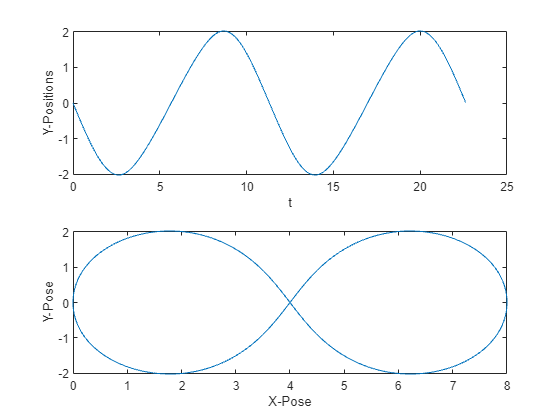


figure(1)
subplot(2,1,1) 
plot(t,pos(:,2))
xlabel('t');
ylabel('Y-Positions');
subplot(2,1,2) 
plot(pos(:,1),pos(:,2))
xlabel('X-Pose')
ylabel('Y-Pose')

function [overall,xunit,yunit] = circle(x,y,r)
% hold on
x_origin = x;
y_origin = y;
radius = r;
th = 0:pi/50:2*pi; % 100 pts
xunit = radius * cos(th) + x_origin;
yunit = radius * sin(th) + y_origin;
z = ones([size(xunit)]);
overall = plot3(xunit, yunit, z, "red",'LineWidth',5);
xlabel('X')
ylabel('Y')
ylabel('Z')
%axis equal
% hold off
end


